# `Εργασία Νευρωνικών Δκτύων - Άσκηση 4`

## `Θεωρητική ανάλυση προβλήματος`

`Το πρόβλημα χρησιμοποιεί την εκπαίδευση νευρωνικού δικτύου για να προβλέψει λύσεις μιας συνάρτησης. Η συνάρτηση είναι πολυωνυμική και απαιτεί για κάθε επίλυση τρεις εισόδους και μια έξοδο. Για εισόδους απο [-1 1].`

clc; clear;
	
lim = linspace(-1,1,200);

[x,y,z] = meshgrid(lim,lim,lim);

out = (z.^2) + (x.^3) - (2 .* x) .* cos(y .* z + 4);

p = patch(isosurface(out))

p =   Patch with properties:

    FaceColor: [0 0 0]
    FaceAlpha: 1
    EdgeColor: [0 0 0]
    LineStyle: '-'
        Faces: [155612×3 double]
     Vertices: [78478×3 double]

  Show all properties


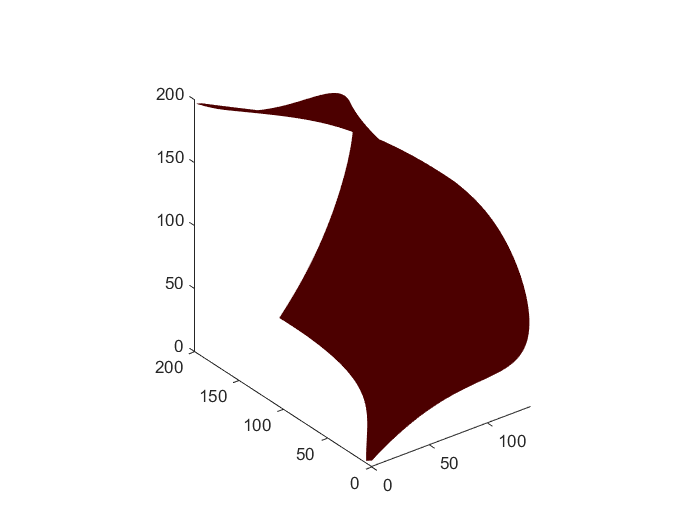

       isonormals(x,y,z,out, p)
       p.FaceColor = 'red';
       p.EdgeColor = 'none';
       daspect([1 1 1])
       view(3)
       camlight; lighting phong

`Αρχίζω να σχεδιάζω το νευρωνικό που θα αποτελείται απο 3 εισόδους και μια έξοδο. Επίσης θα υπάρχουν δύο επίπεδα με 5 και 10 layers το κάθε ένα. Αρχικά όμως πρέπει να δημιουργήσω τα δεδομένα που θα εισάγω για να εκπαιδεύσω αργότερα το δίκτυο. Θα δημιουργηθούν τυχαίες είσοδοι ανάλογα με τον πληθυσμό που θα ορίσω για την εκπαίδευση και την αξιολόγηση του δικτύου αντίστοιχα.`

clc; clear;

%Creating Samples from Function
population = 200;
population_test = 40;

%Importing Data
data = newff_function(population);

`Εφόσοον δημιούργησα τον πληθυσμό μου κάνω τον διαχωρισμό των εισόδων και των εξόδων.`

%Data Seperation
inputs = [data(:,1) data(:,2) data(:,3)]';
targets = data(:,4)';

`Σχεδιασμός γίνεται ως εξής με την αρχιτεκτονική που αναφέρθηκε παραπάνω και τις παρακάτω παραμέτρους.`

%Design Network
scalling = minmax(inputs);
net = newff(scalling,[5,10,1], {'tansig','tansig','purelin'},'traingd');

          See help for NEWFF to update calls to the new argument list.
 



% Define learning parameters 
net.trainParam.show = 50; % The result is shown at every 50th iteration (epoch) 
net.trainParam.lr = 0.01; % Learning rate used in some gradient schemes 
net.trainParam.epochs =1000; % Max number of iterations 
net.trainParam.goal = 1e-5; % Error tolerance; stopping criterion 

`Προχωράμε λοιπόν στη εκπαίδευση με τις εισόδους που δημιουργήσαμε παραπάνω.`

%Train the model:
[net,tr] = train(net,inputs,targets);

`Σε δεύτερη φάση δημιουργούμε διαφορέτικά δεδομένα πάλι με τον ίδιο τρόπο παίρνοντας τυχαίες εισόδους εντός ορίων, πληθυσμού 50 και τα στέλνουμε για αξιολόγηση.`

%Data for Testing:
data_test = newff_function(population_test);
inputs_test = [data_test(:,1) data_test(:,2) data_test(:,3)]';
targets_test = data_test(:,4)';

% Response - output of Neural Netowrk
test = sim(net,inputs_test);

`Τώρα υπολογίζουμε την διαφορά των αποτελεσμάτων που έγινε πρόβλεψη απο το δίκτυο με τα πραγματικά αποτελέσματα που μας έδινε η συνάρτηση.`

% Estimate Mean Square Error
mse = sum((targets_test - test).^2) / population_test;
fprintf('Mean square Error = %.4f\n', mse)

Mean square Error = 0.0932


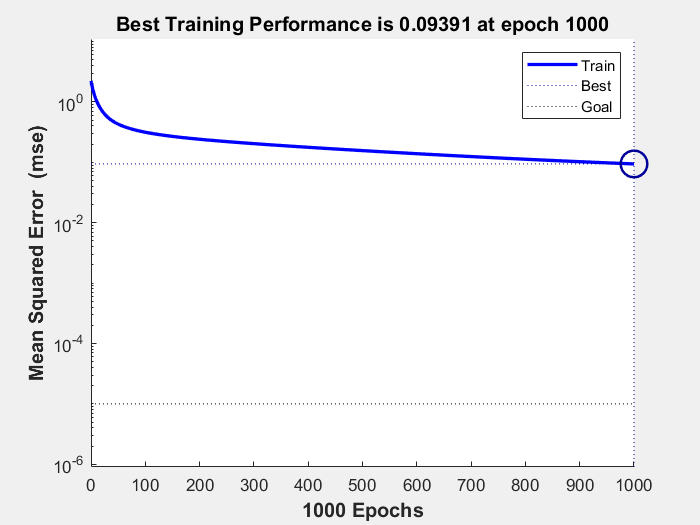

plotperform(tr)

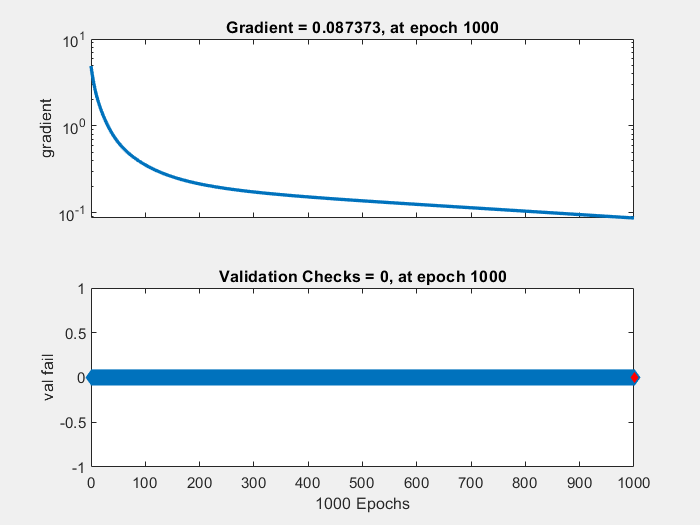

plottrainstate(tr)

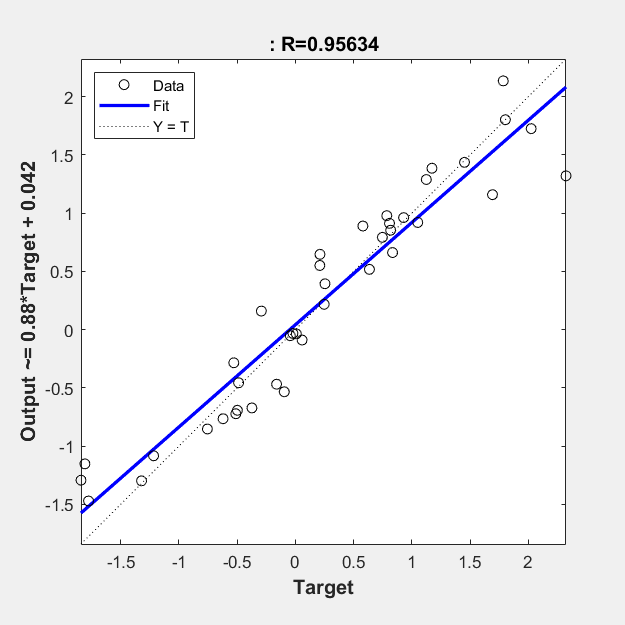

plotregression(targets_test,test)

`Maria Areti Germanou - 57807`